# Checking the Weather Using MATLAB and Python 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

There are benefits and challenges in bringing multiple programming languages together using Application Programming Interfaces (APIs). In this script, you have an existing Python module that contains functions for accessing the OpenWeather API and doing some initial cleaning of the data. To practice using existing code rather than rewriting the functionality into MATLAB, this script walks through using the existing `checkcurrentweather.py` code in the Run Python Code Live Task. The exploration and analysis of the data will happen in MATLAB. This toy example should demonstrate the possibilities for using code provided by others in the framework of code you write yourself. This can provide benefits for collaboration and time savings even when it may well be possible to [rewrite the code](https://www.mathworks.com/help/matlab/ref/webread.html) to use [fewer tools](https://www.mathworks.com/help/matlab/ref/jsondecode.html). 

**Getting started: **Follow the instructions in [Using Python with MATLAB](matlab: edit UsingPythonWithMATLAB.mlx) to ensure that your system is configured to run compatible versions of MATLAB, Python, and the Run Python Code Live Task. 

 **Warning:** This script was written in Python 3.8 and has been tested with Python 3.9 and 3.10. It will not run with Python 2.7. 

## Use Python to pull current information from the OpenWeather API

### Create an OpenWeather account 

- Navigate to [https://home.openweathermap.org/users/sign_up](https://home.openweathermap.org/users/sign_up) to create your account. 

- Once you have an account, visit [https://home.openweathermap.org/home](https://home.openweathermap.org/home) and select **API keys** from the menu

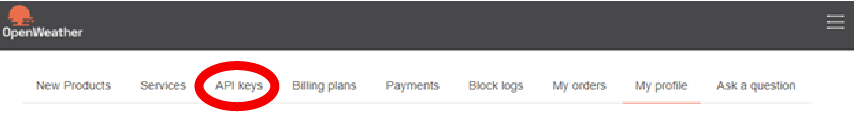

          3. Save your API key in `HelperFunctions` as `myAPIkey.txt` by pasting it here:

if ~exist("myAPIkey.txt","file") || false% Check this box to save a new API key
    % Load your API key and save it in a file
    apikey ="";
    if apikey ~= ""
        writelines(apikey,fullfile("FunctionLibrary","myAPIkey.txt"))
    end
elseif ~isempty(readlines("myAPIkey.txt",EmptyLineRule="skip"))
    % If you already have an API key saved, load it from the file
    apikey = readlines("myAPIkey.txt",EmptyLineRule="skip");
    disp("The API key is: " + apikey)
else
    disp("You need to save an Openweather API key to use this script.")
end

Check that Python is configured properly:

CheckPythonVersion(Flag="ProjectScript")

          5. Choose a location by latitude and longitude, create a label for your location, and make a choice of the unit system. The [units available](https://openweathermap.org/current) from the OpenWeather API are "standard", "metric", or "imperial".

lat = 42.2834;   % Natick, US
lon = -71.3495;  % Natick, US
location = "Natick, US";
unitChoice = "imperial";
% lat = 4.6097;    % Bogota, Colombia
% lon = -74.0817;  % Bogota, Colombia
% location = "Bogota, Colombia"
% unitChoice = "metric";
% lat = 12.9762;   % Bengaluru, India
% lon = 77.6033;   % Bengaluru, India
% location = "Bengaluru, Inda";
% unitChoice = "metric";

        6. Insert a Run Python Code Live Task here and configure it to run the Python code below: 

Note that this requires four input variables: `lat`, `lon`, `apikey`, and `unitChoice`. It also returns one output variable: `currentWeather`. 

% Open the Live Task Run Python Code here

% Python code input
pycode = [...
"import checkcurrentweather",...
"",...
"# Make sure that the Run Python Code Live Task recognizes that unitChoice is a variable",...
"pyUnits = unitChoice",...
"",...
"json_data = checkcurrentweather.get_weather(lat,lon,apikey,units =  pyUnits)",...
"currentWeather = checkcurrentweather.parse_current_json(json_data)"...
];

[currentWeather] = pyrun(pycode, [ "currentWeather" ], ...
      "lat", lat, "lon", lon, "apikey", apikey, "unitChoice", unitChoice)

% Clean up
clear pycode;


## Exploring the results of your API call

### Checking Data Types

The return variable is a Python dictionary. 

class(currentWeather)

This means they are collections of key/value pairs:

currentWeather

You can check the list of keys:

keys(currentWeather)

or even access values:

currentWeather{"feels_like"}

### Converting Data Types

To fully interface between languages, you should convert the Python dictionary into a MATLAB data type. 

  **Try. **Use the `struct` command to create a MATLAB structure from the returned variable `currentWeather`. Name the new variable `curWeather`. Do not suppress the output. 

curWeather = struct(currentWeather)

 **Reflect**. 

- What happened to the keys and values from the Python dictionary?

There are still both MATLAB and Python data types inside `curWeather`. This happens because there is a conservative list of Python data types that can be automatically converted to equivalent MATLAB data types. 

** Exercise 1.**

- Identify two fields that contain MATLAB doubles.

- Identify two fields that contain Python integers.

- Identify two fields that contain Python strings.

**Solution:**

Observe that this structure contains MATLAB doubles

class(curWeather.temp_min)
class(curWeather.wind_deg)

as well as Python integers: 

class(curWeather.current_time)
class(curWeather.timezone)

and Python strings:

class(curWeather.local_time)
class(curWeather.city_name)

### Choosing Data Type Conversions

As the programmer, you have additional information about what type of data is contained in each field. Use this information to choose appropriate MATLAB data types. 

Convert the `py.str` values to MATLAB strings using `string` and the `py.int` values to numeric MATLAB variables using `double. `

curWeather.current_time = double(curWeather.current_time);

curWeather.local_time = string(curWeather.local_time);

Is a string the right data type for `curWeather.local_time`? Let's take a look:

curWeather.local_time

This is actually a better fit as a `datetime` in MATLAB. Convert the data type again:

curWeather.local_time = datetime(curWeather.local_time);
curWeather.local_time

We also don't know what is inside of the list in `curWeather.weather`, let's do a bit of exploring:

curWeather.weather

Which options make the most sense for a Python dictionary containing integers, strings, and alphanumeric codes? There is only one element, a dictionary, in this Python list, so that we can pull it out into a structure:

weatherDescr = curWeather.weather{1};
weather = struct(weatherDescr)

Okay, we can decide which of these values we are interested in. Do you want to explore the [`id` codes](https://openweathermap.org/weather-conditions#Weather-Condition-Codes-2)? Or do you want to see the verbal description of the weather? Do you want to use the [icons](https://openweathermap.org/weather-conditions#How-to-get-icon-URL) from OpenWeatherMap?

Let's start by just looking at the verbal descriptions:

weather.main = string(weather.main);
weather.description = string(weather.description)

Now we've got a verbal description of the weather for the day!

** Exercise 2.**

Convert the remaining Python data types to MATLAB data types.

**Solution:**

curWeather.sunrise = double(curWeather.sunrise);
curWeather.sunset = double(curWeather.sunset);
curWeather.timezone = double(curWeather.timezone);
curWeather.city_name = string(curWeather.city_name);

** Exercise 3.**

Read the [API documentation](https://openweathermap.org/current) to discover how the time is stored, and then read the documentation for [`datetime`](matlab: doc datetime) to find the correct `dateType` to use with `"ConvertFrom"`. Convert `sunrise`, `sunset`, and `current_time` to datetime using the value in `curWeather.timezone` as appropriate.

**Solution:**

curWeather.sunrise = datetime(double(curWeather.sunrise+curWeather.timezone),"ConvertFrom","posixtime");
curWeather.sunset = datetime(double(curWeather.sunset+curWeather.timezone),"ConvertFrom","posixtime");
curWeather.current_time = datetime(double(curWeather.current_time+curWeather.timezone),"ConvertFrom","posixtime");

#### Allow a user to choose the pressure units

From the API, we know that the units of pressure are hectopascals, hPa. This is not a common unit for presenting atmospheric pressure. The code below converts the value into more common units such as millimeters of mercury, standard atmospheres, or bars. 

  **Try**. 

- Run this section and observe the results.

- Change the value of `pUnit`to `"atm"` and run this section again.

- Add a live control to set the `pUnit` using a dropdown menu. The options should be `mmHg`, `atm`, or `bar`.

% Set up a symbolic unit 
u = symunit;
% create a symbolic pressure variable with units
curPressure = curWeather.pressure*u.hPa;
% Choose a unit you want to use for displaying the results
pUnit = "mmHg";

switch pUnit
    case "mmHg"
        curPressure = rewrite(curPressure,u.mmHg);
    case "atm"
        curPressure = rewrite(curPressure,u.atm);
    case "bar"
        curPressure = rewrite(curPressure,u.bar);
end

% Convert from symbolic representations to doubles and strings
% to display the results
[pressure,pUnits] = separateUnits(curPressure);
pressure = double(pressure);
pLabel = symunit2str(pUnits(1));

disp("The pressure is " + pressure + " " + pLabel + ".")

##  Creating a Simple Interactive Live Weather Display

Follow the instructions in [CreateCurrentWeatherAppSoln.mlx](matlab:open('./CreateCurrentWeatherAppSoln.mlx'))

## Further Explorations

If this has whet your appetite, it is possible to go much farther with integrating code back and forth between [MATLAB and Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html). 

- Documentation on [calling Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html)

- Documentation on [calling MATLAB from Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))